# **Fig 2 - 2025 Sep Version **

## **Fig. 2 a and b**

clear all; close all; clc;

data_LocalLoad_LocalOpti_thunder = readtable("../data/Data4Figure/Line74TemporalLoad_LocalOpti.csv");
data_LocalLoad_SystemOpti_thunder = readtable("../data/Data4Figure/Line74TemporalLoad_SystemOpti.csv");



mode_list = ["SystemLoad", "NetLoad", "OnlyV2G", "V1G", "V2G", "UncontrolledCharging"];
DisplayName_list = ["No PV, no EV", "PV only", "V2G Only", "PV + V1G", "PV + V2G", "PV + Uncontrolled charging"];
plot_cols = [1, 3, 2, 5, 6];      % order to plot (5 lines total)

% x-axis (15-min)
t = (0.25:0.25:24)';

data_SystemOpt_th = smoothdata(table2array(data_LocalLoad_SystemOpti_thunder),...
    "movmean", 1);
data_LocalOpt_th  = smoothdata(table2array(data_LocalLoad_LocalOpti_thunder ),...
    "movmean", 1);

%% ---------------- Nature-ish figure & axes defaults ----------------
set(groot,'defaultAxesFontName','Helvetica');
set(groot,'defaultTextFontName','Helvetica');

fig_w_cm = 18.3;   % two-column width
fig_h_cm = 7.0;    % compact height for 1×2
figure('Units','centimeters','Position',[2 2 fig_w_cm fig_h_cm]);

tiledlayout(1,2, 'Padding','compact', 'TileSpacing','compact');

base_pt   = 7.5;   % body text
label_pt  = 8.5;   % axis labels
line_w    = 1.5;   % line width


C = struct();
C.deepRed      = [0.70 0.15 0.15];
C.lightRed     = [0.85 0.45 0.45];
C.blue         = [0.20 0.50 0.80];
C.lightBlue    = [0.45 0.70 0.90];
C.blueGray = [0.25 0.25 0.25];   

% Map colors to each curve (in the order of plot_cols)
% 1: SystemLoad -> blueGray (solid)
% 3: OnlyV2G    -> lightRed (dashed)
% 2: NetLoad    -> blue (solid)
% 5: V2G        -> deepRed (solid)
% 6: Uncontrolled -> lightBlue (dotted)
curveColors = containers.Map( ...
    num2cell(plot_cols), ...
    {C.blueGray, C.lightRed, C.blue, C.deepRed, C.lightBlue} ...
);



curveStyles = containers.Map( ...
    num2cell(plot_cols), ...
    {':', '--', '-', '-', "-."} ... % OnlyV2G='--', Uncontrolled=':'
);



%% ---------------- (1) System-level optimization (thunder) ----------------
ax1 = nexttile; hold(ax1,'on');
for k = 1:numel(plot_cols)
    ci = plot_cols(k);
    plot(ax1, t, data_SystemOpt_th(:, ci), ...
        'LineStyle', curveStyles(ci), ...
        'Color',     curveColors(ci), ...
        'LineWidth', line_w, ...
        'DisplayName', DisplayName_list(ci));

end
xlabel(ax1, 'Hour of day', 'FontSize', label_pt);
ylabel(ax1, 'Line load (MW)', 'FontSize', label_pt);
title(ax1, 'System-level optimization', 'FontSize', base_pt);
xlim(ax1, [0 24]); ylim(ax1, [200 700]);grid(ax1, 'on'); 

% Axes aesthetics
set(ax1, 'FontSize', base_pt, 'TickDir','out', 'LineWidth',0.8, ...
    'Box','off', 'XMinorTick','on', 'YMinorTick','on', 'TickLength',[0.015 0.01]);


%% ---------------- (2) District-level optimization (thunder) ----------------
ax2 = nexttile; hold(ax2,'on');
for k = 1:numel(plot_cols)
    ci = plot_cols(k);
    plot(ax2, t, data_LocalOpt_th(:, ci), ...
        'LineStyle', curveStyles(ci), ...
        'Color',     curveColors(ci), ...
        'LineWidth', line_w, ...
        'DisplayName', DisplayName_list(ci));

end
xlabel(ax2, 'Hour of day', 'FontSize', label_pt);
ylabel(ax2, 'Line load (MW)', 'FontSize', label_pt);
title(ax2, 'District-level optimization', 'FontSize', base_pt);
xlim(ax2, [0 24]); ylim(ax2, [200 700]); grid(ax2, 'on');

set(ax2, 'FontSize', base_pt, 'TickDir','out', 'LineWidth',0.8, ...
    'Box','off', 'XMinorTick','on', 'YMinorTick','on', 'TickLength',[0.015 0.01]);

% Keep only one legend (left tile), to reduce clutter:
lg2 = legend(ax2, 'Location','eastoutside'); %#ok<LAXES>
set(lg2,'Box','off', 'FontSize', base_pt);


left_margin   = 0.08;   % left margin for axes
right_margin  = 0.18;   % reserve space for legend on the right
gutter        = 0.08;   % gap between the two subplots
bottom_margin = 0.14;
axes_height   = 0.75;


axes_width = (1 - left_margin - right_margin - gutter) / 2;


set(ax1, 'Units','normalized', 'Position', ...
    [left_margin, bottom_margin, axes_width, axes_height]);
set(ax2, 'Units','normalized', 'Position', ...
    [left_margin + axes_width + gutter, bottom_margin, axes_width, axes_height]);




%% ---------------- Tighten tiles ----------------

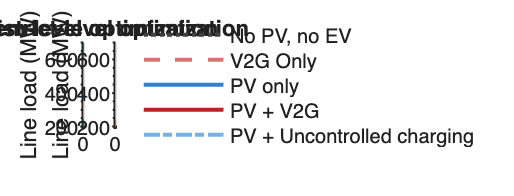

drawnow;
axs = [ax1, ax2];
for k = 1:numel(axs)
    outerpos = axs(k).OuterPosition; ti = axs(k).TightInset;
    left   = outerpos(1) + ti(1);
    bottom = outerpos(2) + ti(2);
    ax_w   = outerpos(3) - ti(1) - ti(3);
    ax_h   = outerpos(4) - ti(2) - ti(4);

end



%{ %}
%% ---------------- Optional: export (vector PDF) ----------------
outPath = "../results/Fig2_ExamplaryLine_System_vs_district_" +...
    string(datetime("now", "Format", "yyyy-MM-dd")) + ".pdf";

exportgraphics(gcf, outPath, ...
    'ContentType','vector', 'BackgroundColor','none');
%{ %}




## Maximum load of all lines - system and district-level optimization

clear all; close all; clc;


path_file_PeakLoadData = "../data/Data4Figure/PeakDCPowerFlow.csv";

T_combined = readtable(path_file_PeakLoadData);


numCols = width(T_combined);
blockSize = ceil(numCols / 4);

T_all = cell(1,4);
for i = 1:4
    colStart = (i-1)*blockSize + 1;
    colEnd   = min(i*blockSize, numCols);
    T_each_new = T_combined(:, colStart:colEnd);
    T_each_new.Properties.VariableNames = {'UncontrolledCharging', 'V1G', 'V2G', 'SystemLoad'};
    T_all{i} = T_each_new;
end








### Fig 2 c d e f 

%% --- Figure: 2×2 layout ---
fig_w_cm = 18.3;   % two-column width
fig_h_cm = 12.0;   % comfortable height for 2×2
figure('Units','centimeters','Position',[2 2 fig_w_cm fig_h_cm]);
tiledlayout(2,2,'Padding','compact','TileSpacing','compact');


set(groot,'defaultAxesFontName','Helvetica');
set(groot,'defaultTextFontName','Helvetica');

base_pt  = 7.5;    % tick/legend
label_pt = 8.5;    % axis labels
line_w   = 1.1;
gridCol  = 0.85*[1 1 1];


colBlue      = [0.20 0.50 0.80];
colBlueDark  = [0.10 0.35 0.65];
colRed       = [0.80 0.30 0.30];
colRedDark   = [0.65 0.15 0.15];


lightRed   = [245,229,214]./255;
lightGreen = [211,222,208]./255;


x_min = 0; x_max = 1000;
y_min = 0; y_max = 1000;


panels = {
  'PV_uncontrolled_charging_without_thunderstorms', 'PV_uncontrolled_charging_with_thunderstorms',         'PV+V2G: system-level optimization\n(without thunderstorms)',  colRedDark
  'PV_uncontrolled_charging_without_thunderstorms', 'PV_V2G_LocalOptimization_without_thunderstorms',      'PV+V2G: district-level optimization\n(without thunderstorms)',      colBlueDark         
  'PV_uncontrolled_charging_with_thunderstorms',    'PV_V2G_SystemOptimization_with_thunderstorms',        'PV+V2G: system-level optimization\n(with thunderstorms)',            colRed   
  'PV_uncontrolled_charging_with_thunderstorms',    'PV_V2G_LocalOptimization_with_thunderstorms',         'PV+V2G: district-level optimization\n(with thunderstorms)',         colBlue    
};

for k = 1:4
    nexttile; hold on;

    T = T_all{k};
    % ---- Data ----
    x_all = T{:, "UncontrolledCharging"};
    y_all = T{:, "V2G"};
    
    idx = x_all >= x_min & x_all <= x_max;
    x = x_all(idx);  y = y_all(idx);

    slope = (x(:)' * y(:)) / (x(:)' * x(:));   
   
    y_fit = slope * x;
    disp("k: "+num2str(k)+" ;slope: " + num2str(slope));

    fill([x_min x_max x_max x_min], [y_min y_min y_max y_min], lightGreen, 'EdgeColor','none', 'FaceAlpha',0.5);
    fill([x_min x_max x_min x_min], [y_max y_max y_min y_max], lightRed,   'EdgeColor','none', 'FaceAlpha',0.5);

    scatter(x, y, 8, 'b', 'filled', 'MarkerEdgeColor', panels{k,4}, 'LineWidth',0.6);

    plot([x_min, x_max], [x_min, x_max], 'k--', 'LineWidth', 0.9);

    plot(x, y_fit, '-', 'Color', panels{k,4}, 'LineWidth', line_w+0.2, ...
        'DisplayName', sprintf('Fit: y = %.2fx', slope));

    % ---- Labels, limits, grid ----
    xlabel("Max load 'PV + uncontrolled charging' (MW)", 'FontSize', label_pt);
    ylabel('Max load (MW)', 'FontSize', label_pt);
    text(150, 900, sprintf(panels{k,3}), ...
     'FontSize', 8, 'FontWeight', 'bold', 'Color', 'k');

    xlim([x_min, x_max]); ylim([y_min, y_max]);
    grid on; ax = gca; ax.GridColor = gridCol;

    % ---- Axes look ----
    set(ax, 'FontSize', base_pt, 'TickDir','out', 'LineWidth',0.8, ...
        'Box','off', 'XMinorTick','on', 'YMinorTick','on', 'TickLength',[0.015 0.01]);

    if k == 1

       text(300, 500, 'load increase', 'FontSize', 8, 'Rotation', 30, 'FontWeight', 'normal');
       text(400, 200, 'load decrease', 'FontSize', 8, 'Rotation', 30, 'FontWeight', 'normal');

    end


end

k: 1 ;slope: 0.83596
k: 2 ;slope: 0.78149
k: 3 ;slope: 1.0433
k: 4 ;slope: 0.85023




drawnow;
axs = findall(gcf,'Type','axes');
for i = 1:numel(axs)
    outerpos = axs(i).OuterPosition; ti = axs(i).TightInset;
    left   = outerpos(1) + ti(1);
    bottom = outerpos(2) + ti(2);
    ax_w   = outerpos(3) - ti(1) - ti(3);
    ax_h   = outerpos(4) - ti(2) - ti(4);
    set(axs(i),'Position',[left bottom ax_w ax_h]);
end

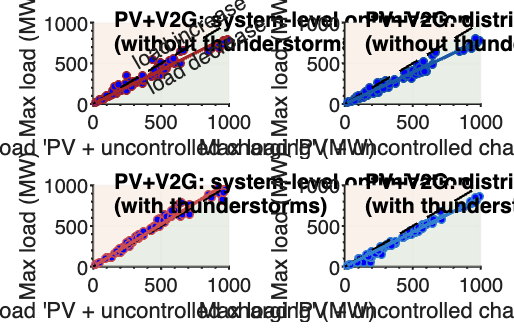



%{ %} 
%% ---------------- export (vector PDF) ----------------
outPath = "../results/Fig2_AllLines_System_vs_district_" +...
    string(datetime("now", "Format", "yyyy-MM-dd")) + ".pdf";

exportgraphics(gcf, outPath, ...
    'ContentType','vector', 'BackgroundColor','none');

%{%}

### Fig S13, V2G, load higher than 1000 MW


fig_w_cm = 18.3;   % two-column width
fig_h_cm = 12.0;   % comfortable height for 2×2
figure('Units','centimeters','Position',[2 2 fig_w_cm fig_h_cm]);
tiledlayout(2,2,'Padding','compact','TileSpacing','compact');

set(groot,'defaultAxesFontName','Helvetica');
set(groot,'defaultTextFontName','Helvetica');

base_pt  = 7.5;    
label_pt = 8.5;   
line_w   = 1.1;
gridCol  = 0.85*[1 1 1];


colBlue      = [0.20 0.50 0.80];
colBlueDark  = [0.10 0.35 0.65];
colRed       = [0.80 0.30 0.30];
colRedDark   = [0.65 0.15 0.15];

lightRed   = [245,229,214]./255;
lightGreen = [211,222,208]./255;


x_min = 1000; x_max = 3500;
y_min = 1000; y_max = 3500;


panels = {
  'PV_uncontrolled_charging_without_thunderstorms', 'PV_uncontrolled_charging_with_thunderstorms',         'PV+V2G: system-level optimization\n(without thunderstorms)',  colRedDark
  'PV_uncontrolled_charging_without_thunderstorms', 'PV_V2G_LocalOptimization_without_thunderstorms',      'PV+V2G: district-level optimization\n(without thunderstorms)',      colBlueDark         
  'PV_uncontrolled_charging_with_thunderstorms',    'PV_V2G_SystemOptimization_with_thunderstorms',        'PV+V2G: system-level optimization\n(with thunderstorms)',            colRed   
  'PV_uncontrolled_charging_with_thunderstorms',    'PV_V2G_LocalOptimization_with_thunderstorms',         'PV+V2G: district-level optimization\n(with thunderstorms)',         colBlue    
};

for k = 1:4
    nexttile; hold on;

    T = T_all{k};

    
    x_all = T{:, "UncontrolledCharging"};
    y_all = T{:, "V2G"};


    idx = x_all >= x_min & x_all <= x_max;
    x = x_all(idx);  y = y_all(idx);

    slope = (x(:)' * y(:)) / (x(:)' * x(:));   
    
    y_fit = slope * x;

    fill([0 x_max x_max 0], [0 0 y_max 0], lightGreen, 'EdgeColor','none', 'FaceAlpha',0.5);
    fill([0 x_max 0 0], [y_max y_max 0 y_max], lightRed,   'EdgeColor','none', 'FaceAlpha',0.5);

    scatter(x, y, 8, 'b', 'filled', 'MarkerEdgeColor', panels{k,4}, 'LineWidth',0.6);

    plot([0, x_max], [0, x_max], 'k--', 'LineWidth', 0.9);

    plot(x, y_fit, '-', 'Color', panels{k,4}, 'LineWidth', line_w+0.2, ...
        'DisplayName', sprintf('Fit: y = %.2fx', slope));

    xlabel("Max load 'PV + uncontrolled charging' (MW)", 'FontSize', label_pt);
    ylabel('Max load (MW)', 'FontSize', label_pt);
    text(500, 900*2.5+1000, sprintf(panels{k,3}), ...
     'FontSize', 8, 'FontWeight', 'bold', 'Color', 'k');

    xlim([0, x_max]); ylim([0, y_max]);
    grid on; ax = gca; ax.GridColor = gridCol;

    set(ax, 'FontSize', base_pt, 'TickDir','out', 'LineWidth',0.8, ...
        'Box','off', 'XMinorTick','on', 'YMinorTick','on', 'TickLength',[0.015 0.01]);

    if k == 1
       text(300+1000, 500+1100, 'load increase', 'FontSize', 8, 'Rotation', 30, 'FontWeight', 'normal');
       text(400+1000, 200+900, 'load decrease', 'FontSize', 8, 'Rotation', 30, 'FontWeight', 'normal');

    end


end

drawnow;
axs = findall(gcf,'Type','axes');
for i = 1:numel(axs)
    outerpos = axs(i).OuterPosition; ti = axs(i).TightInset;
    left   = outerpos(1) + ti(1);
    bottom = outerpos(2) + ti(2);
    ax_w   = outerpos(3) - ti(1) - ti(3);
    ax_h   = outerpos(4) - ti(2) - ti(4);
    set(axs(i),'Position',[left bottom ax_w ax_h]);
end

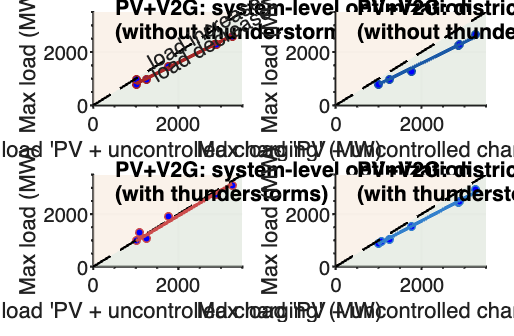



%{  %}
%% ---------------- export (vector PDF) ----------------
outPath = "../results/Load_HigherThan_1000_" +...
    string(datetime("now", "Format", "yyyy-MM-dd")) + ".pdf";

exportgraphics(gcf, outPath, ...
    'ContentType','vector', 'BackgroundColor','none');

%{ %}



### Fig S14, V1G

%%%% Figure V1G

fig_w_cm = 18.3;  
fig_h_cm = 12.0;   
figure('Units','centimeters','Position',[2 2 fig_w_cm fig_h_cm]);
tiledlayout(2,2,'Padding','compact','TileSpacing','compact');


set(groot,'defaultAxesFontName','Helvetica');
set(groot,'defaultTextFontName','Helvetica');

base_pt  = 7.5;   
label_pt = 8.5;    
line_w   = 1.1;
gridCol  = 0.85*[1 1 1];

colBlue      = [0.20 0.50 0.80];
colBlueDark  = [0.10 0.35 0.65];
colRed       = [0.80 0.30 0.30];
colRedDark   = [0.65 0.15 0.15];

lightRed   = [245,229,214]./255;
lightGreen = [211,222,208]./255;

x_min = 0; x_max = 1000;
y_min = 0; y_max = 1000;

panels = {
  'PV_uncontrolled_charging_without_thunderstorms', 'PV_uncontrolled_charging_with_thunderstorms',         'PV+V1G: system-level optimization\n(without thunderstorms)',  colRedDark
  'PV_uncontrolled_charging_without_thunderstorms', 'PV_V1G_LocalOptimization_without_thunderstorms',      'PV+V1G: district-level optimization\n(without thunderstorms)',      colBlueDark         
  'PV_uncontrolled_charging_with_thunderstorms',    'PV_V1G_SystemOptimization_with_thunderstorms',        'PV+V1G: system-level optimization\n(with thunderstorms)',            colRed   
  'PV_uncontrolled_charging_with_thunderstorms',    'PV_V1G_LocalOptimization_with_thunderstorms',         'PV+V1G: district-level optimization\n(with thunderstorms)',         colBlue    
};

for k = 1:4
    nexttile; hold on;

    T = T_all{k};

    x_all = T{:, "UncontrolledCharging"};
    y_all = T{:, "V1G"};

    idx = x_all >= x_min & x_all <= x_max;
    x = x_all(idx);  y = y_all(idx);

    slope = (x(:)' * y(:)) / (x(:)' * x(:));   

    y_fit = slope * x;


    fill([x_min x_max x_max x_min], [y_min y_min y_max y_min], lightGreen, 'EdgeColor','none', 'FaceAlpha',0.5);
    fill([x_min x_max x_min x_min], [y_max y_max y_min y_max], lightRed,   'EdgeColor','none', 'FaceAlpha',0.5);

    scatter(x, y, 8, 'b', 'filled', 'MarkerEdgeColor', panels{k,4}, 'LineWidth',0.6);

    plot([x_min, x_max], [x_min, x_max], 'k--', 'LineWidth', 0.9);

    plot(x, y_fit, '-', 'Color', panels{k,4}, 'LineWidth', line_w+0.2, ...
        'DisplayName', sprintf('Fit: y = %.2fx', slope));

    xlabel("Max load 'PV + uncontrolled charging' (MW)", 'FontSize', label_pt);
    ylabel('Max load (MW)', 'FontSize', label_pt);

    text(150, 900, sprintf(panels{k,3}), ...
     'FontSize', 8, 'FontWeight', 'bold', 'Color', 'k');

    xlim([x_min, x_max]); ylim([y_min, y_max]);
    grid on; ax = gca; ax.GridColor = gridCol;

    set(ax, 'FontSize', base_pt, 'TickDir','out', 'LineWidth',0.8, ...
        'Box','off', 'XMinorTick','on', 'YMinorTick','on', 'TickLength',[0.015 0.01]);
    if k == 1
       text(300, 500, 'load increase', 'FontSize', 8, 'Rotation', 30, 'FontWeight', 'normal');
       text(400, 200, 'load decrease', 'FontSize', 8, 'Rotation', 30, 'FontWeight', 'normal');

    end


end

drawnow;
axs = findall(gcf,'Type','axes');
for i = 1:numel(axs)
    outerpos = axs(i).OuterPosition; ti = axs(i).TightInset;
    left   = outerpos(1) + ti(1);
    bottom = outerpos(2) + ti(2);
    ax_w   = outerpos(3) - ti(1) - ti(3);
    ax_h   = outerpos(4) - ti(2) - ti(4);
    set(axs(i),'Position',[left bottom ax_w ax_h]);
end

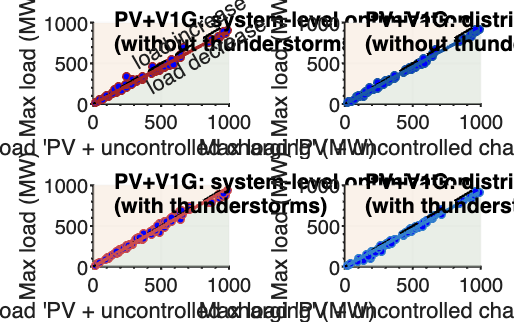




%{  %}
%% ---------------- export (vector PDF) ----------------
outPath = "../results/AllLines_V1G_System_vs_district_" +...
    string(datetime("now", "Format", "yyyy-MM-dd")) + ".pdf";

exportgraphics(gcf, outPath, ...
    'ContentType','vector', 'BackgroundColor','none');

%{ %}





